Simulation 1 completed
Simulation 2 completed
Simulation 3 completed
Simulation 4 completed
Simulation 5 completed
Simulation 6 completed
Simulation 7 completed
Simulation 8 completed
Simulation 9 completed
Simulation 10 completed
Simulation 11 completed
Simulation 12 completed
Simulation 13 completed
Simulation 14 completed
Simulation 15 completed
Simulation 16 completed
Simulation 17 completed
Simulation 18 completed
Simulation 19 completed
Simulation 20 completed
Simulation 21 completed
Simulation 22 completed
Simulation 23 completed
Simulation 24 completed
Simulation 25 completed
Simulation 26 completed
Simulation 27 completed
Simulation 28 completed
Simulation 29 completed
Simulation 30 completed
Simulation 31 completed
Simulation 32 completed
Simulation 33 completed
Simulation 34 completed
Simulation 35 completed
Simulation 36 completed
Simulation 37 completed
Simulation 38 completed
Simulation 39 completed
Simulation 40 completed
Simulation 41 completed
Simulation 42 completed
S

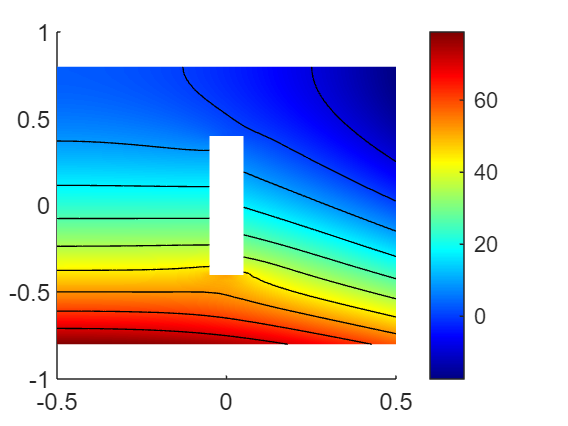

Simulation 100 completed


% Define parameters
numSimulations = 100;
imagePath = 'D:\AcadsSem7\BTP_One\MATLAB_Simulations\Learning_Parallel_Sims\ChatGpt5Images\';

% Loop through simulations
for simIdx = 1:numSimulations
    % Run thermal simulation using the PDE Toolbox
    temperatureProfile = runThermalSimulation();
    
    % Save temperature profile image
    saveTemperatureProfileImage(temperatureProfile, imagePath, simIdx);
    
    % Extract contours and save contour image
    %contourImage = extractContours(temperatureProfile);
    %saveContourImage(contourImage, imagePath, simIdx);
    
    % Display progress
    disp(['Simulation ', num2str(simIdx), ' completed']);
end


% Simulation function using PDE Toolbox

function temperatureProfile = runThermalSimulation()
    % Create PDE model
    thermalmodel = createpde("thermal", "transient");
    geometryFromEdges(thermalmodel,@crackg);
    pdegplot(thermalmodel,"EdgeLabels","on")
    ylim([-1,1])
    axis equal
    
    thermalProperties(thermalmodel,"ThermalConductivity",0.1,...
                               "MassDensity", 10,...
                               "SpecificHeat",0.1);
 
    thermalBC(thermalmodel,"Edge",1,"Temperature",randi([0, 100]));
    thermalBC(thermalmodel,"Edge",2,"Temperature",randi([0, 100]));
    thermalBC(thermalmodel,"Edge",3,"Temperature",randi([0, 100]));
    thermalBC(thermalmodel,"Edge",4,"Temperature",randi([0, 100]));
    thermalBC(thermalmodel,"Edge",1,"HeatFlux",randi([-10, 10]));
    thermalBC(thermalmodel,"Edge",2,"HeatFlux",randi([-10, 10]));
    thermalBC(thermalmodel,"Edge",3,"HeatFlux",randi([-10, 10]));
    thermalBC(thermalmodel,"Edge",4,"HeatFlux",randi([-10, 10]));
   

    thermalIC(thermalmodel,0);
    generateMesh(thermalmodel);

    %pdemesh(thermalmodel)
    tlist = 0:0.5:5;
    temperatureProfile = solve(thermalmodel,tlist);
    pdeplot(thermalmodel,"XYData",temperatureProfile.Temperature(:,end), ...
                     "Contour","on",...
                     "ColorMap","jet")
end

% Image saving function for temperature profile
function saveTemperatureProfileImage(temperatureProfile, imagePath, simIdx)
    % Create a new figure
    figure;
    
    % Create a pdeplot for the 2D temperature data
    pdeplot(temperatureProfile.Mesh.Nodes, [], temperatureProfile.Mesh.Elements, 'XYData', temperatureProfile.Temperature(:,end),'ColorMap', 'jet');
    
    % Add title and labels
    title(['Temperature Profile (Simulation ', num2str(simIdx), ')']);
    xlabel('X');
    ylabel('Y');
    
    % Save the pdeplot as a PNG image
    tempImageName = sprintf('TemperatureProfile_%d.png', simIdx);
    tempImagePath = fullfile(imagePath, tempImageName);
    savePDEPlotAsPNG(gcf, tempImagePath);
    
    % Close the figure
    close(gcf);
end

% Function to save pdeplot as PNG
function savePDEPlotAsPNG(fig, imagePath)
    % Save the figure as PNG
    saveas(fig, imagePath, 'png');
end

% Function to extract contours
function contourImage = extractContours(temperatureProfile)
    % Create a new figure
    figure;
    
    % Create a pdecontour plot
    contourf(temperatureProfile.Mesh.Nodes, temperatureProfile.Mesh.Elements, 'XYData', temperatureProfile.Temperature);
    
    % Add title and labels
    title('Temperature Contours');
    xlabel('X');
    ylabel('Y');
    
    % Capture the contour plot
    contourImage = getframe(gcf);
    
    % Close the figure
    close(gcf);
end

% Function to save contour image
function saveContourImage(contourImage, imagePath, simIdx)
    % Save the contour image as a PNG
    contourImageName = sprintf('ContourImage_%d.png', simIdx);
    contourImagePath = fullfile(imagePath, contourImageName);
    imwrite(contourImage.cdata, contourImagePath);
end


function boundaryConditionsString = getAppliedBoundaryConditionsAsString(model)
    boundaryConditions = model.BoundaryConditions;
    boundaryConditionsString = '';
    for i = 1:length(boundaryConditions)
        condition = boundaryConditions(i);
        conditionString = char(condition);
        boundaryConditionsString = [boundaryConditionsString, 'Boundary ', num2str(i), ': ', conditionString, '\n'];
    end
end




% Function to append boundary conditions string to a text file
function appendBoundaryConditionsToFile(boundaryConditionsString, filePath)
    % Open the file in append mode
    fid = fopen(filePath, 'a');
    
    % Check if the file was opened successfully
    if fid == -1
        error('Failed to open the file.');
    end
    
    % Append the boundary conditions string to the file
    fprintf(fid, '%s', boundaryConditionsString);
    
    % Close the file
    fclose(fid);
end
